# Recursive Mean Algorithm

[YouTube](https://www.youtube.com/watch?v=HCd-leV8OkU&t=825s)

clear all
addpath(genpath('D:\OneDrive\MATLAB_FILES\UsefulFunctions'));
% edit AvgFilter.mlx;

## Example

The goal is approximate voltage of 14.4[v] given random normally distributed noise of 4[v]

getVolt = @() 14.4 + 0.5*randn;

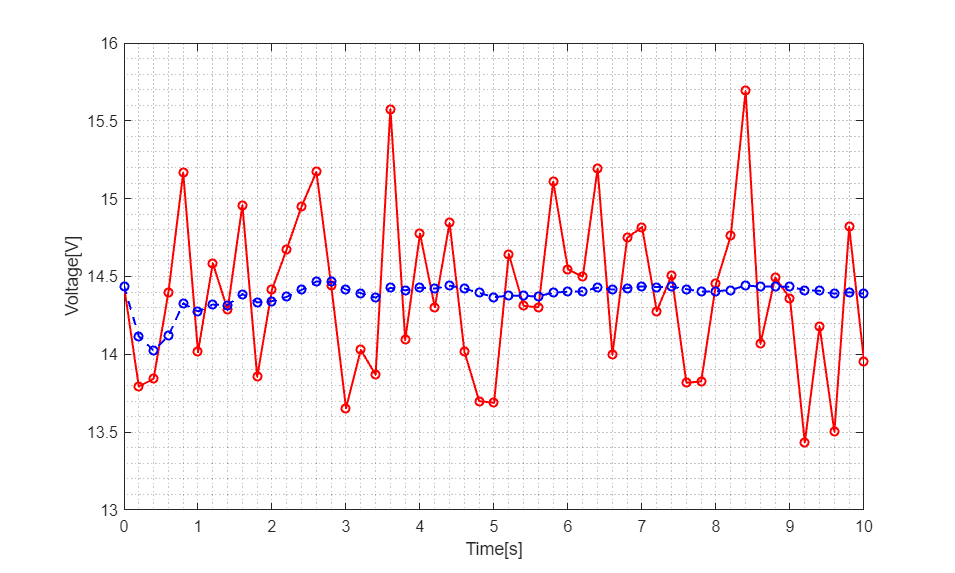

dt = 0.2;
t = (0:dt:10)';
Nsamples = length(t);

xk_Vec = zeros(Nsamples,1);
avg_Vec = zeros(Nsamples,1);


for k = 1:Nsamples

    xk_Vec(k) = getVolt();
    avg_Vec(k) = AvgFilter(xk_Vec(k));

end

figure('Position',[0 0 1000 600])
plot(t, xk_Vec, 'ro-', 'LineWidth',1.5,'DisplayName','Measurement'); hold on;
plot(t, avg_Vec, 'bo--','LineWidth',1.5,'DisplayName','Average');
xlabel('Time[s]')
ylabel('Voltage[V]')
grid minor
set(gca, 'Fontsize', 12)